initSim

Cbase1v = 1.4847e+03

l_f = 0.0265

r_f = 0.0063

SCR_grid = 5

z_grid = 0.2000

r_grid = 0.0632

x_grid = 0.1897

l_grid = 6.0395e-04

R_grid = 0.0134

L_grid = 1.2780e-04

R_mv = 0.6000

L_mv = 0.0034

x_mv_tot = 113.2518

x_hv_tot = 18.8496

r_mv_tot = 0.0912

r_hv_tot = 0.0013

ans = 1.4293e+03

k_p_p_vsm = 0.6000

k_p_q_vsm = -0.0500

k_d_vsm = 70

H_vsm = 3

ki_q = 314.1593

V_dc_base = 1.1268e+03

V_dc = 1.1268e+03

C_dc = 0.0236

ans = 1.5915e-05

I_dc_base = 1.3312e+03

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f

L_f = 0.0265

R_f = r_f

R_f = 0.0063

% plant
    
G_plant = 1/(s*L_f+R_f)

G_plant =
 
          1
  -----------------
  0.0265 s + 0.0063
 
Continuous-time transfer function.
Model Properties


f_sw = 10000

f_sw = 10000

omega_c = f_sw/20*2*pi

omega_c = 3.1416e+03

f_c = omega_c/(2*pi)

f_c = 500.0000

Kp_cc = 60%1/Vbase_lv;

Kp_cc = 60

Ki_cc = 0.08%1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 

Ki_cc = 0.0800

G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)

G_cc =
 
  4.8 s + 60
  ----------
    0.08 s
 
Continuous-time transfer function.
Model Properties


% G_cc = Kp_cc + Ki_cc/s

v_od = 1;
v_od_m = v_od

v_od_m = 1



i_fd = 0;
i_fd_m = i_fd;
i_fd_ref = 1;
i_fq = 0;
i_fq_m = i_fq;

e_fd = i_fd_ref-i_fd_m;

omega = omega_nom/omega_nom

omega = 1



v_td = e_fd*G_cc-omega*L_f*i_fq_m-v_od_m;

i_fd = (v_td - v_od)*G_plant;

G_openl = G_cc*G_plant

G_openl =
 
         4.8 s + 60
  ------------------------
  0.00212 s^2 + 0.000504 s
 
Continuous-time transfer function.
Model Properties


G_cl = G_openl/(1+G_openl)

G_cl =
 
          0.01018 s^3 + 0.1296 s^2 + 0.03024 s
  ----------------------------------------------------
  4.494e-06 s^4 + 0.01018 s^3 + 0.1296 s^2 + 0.03024 s
 
Continuous-time transfer function.
Model Properties


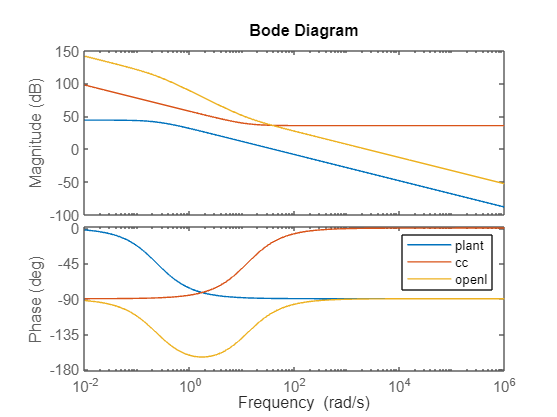


bode(G_plant,G_cc,G_openl,{10e-3,10e5})
legend('plant', 'cc','openl')

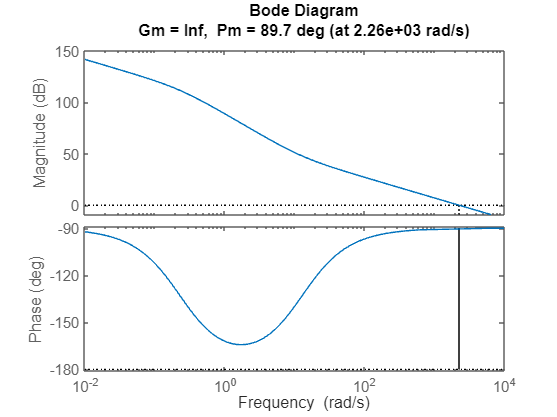



margin(G_openl)

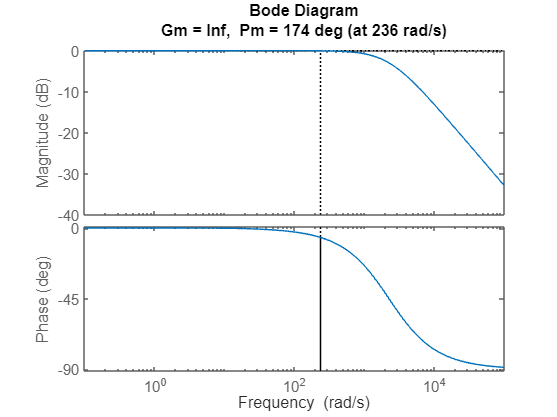

margin(G_cl)

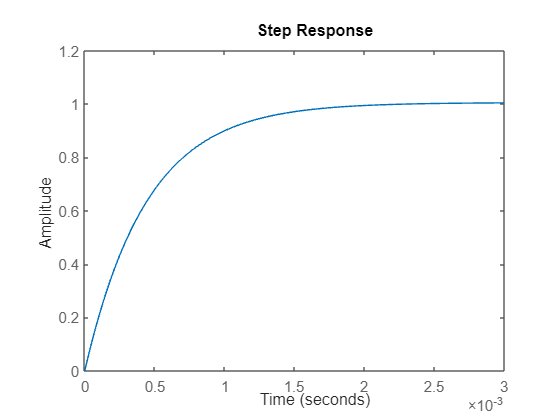

step(G_cl)

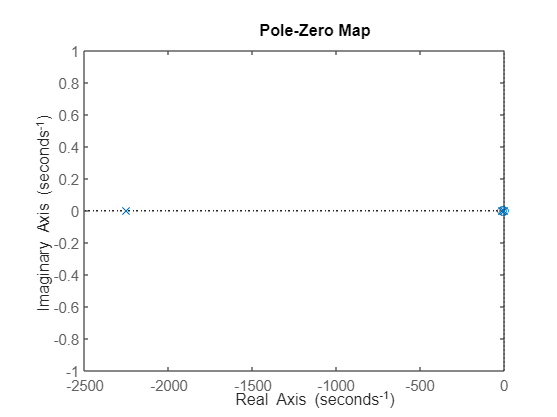

pzmap(G_cl)